## MAE384 Group Project Part 1

Osmond Chong

MAE384

November 27,2024

Professor Peet

#### Influenza

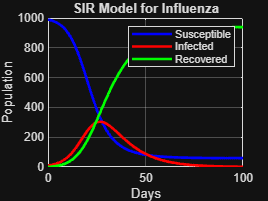

% Initial conditions
S0 = 990; 
I0 = 10; 
R0 = 0;   
N = S0 + I0 + R0;           
beta = 0.3;                  
gamma = 0.1;                
h = 1;                      
T = 100;                     

% Time steps
time = 0:h:T;

% Arrays for populations
S = zeros(length(time), 1);
I = zeros(length(time), 1);
R = zeros(length(time), 1);

% Set initial values
S(1) = S0; 
I(1) = I0; 
R(1) = R0;

% Runge-Kutta method for solving SIR equations
for t = 1:length(time)-1
    k1_S = -beta * S(t) * I(t) / N;
    k1_I = beta * S(t) * I(t) / N - gamma * I(t);
    k1_R = gamma * I(t);
    
    k2_S = -beta * (S(t) + 0.5 * h * k1_S) * (I(t) + 0.5 * h * k1_I) / N;
    k2_I = beta * (S(t) + 0.5 * h * k1_S) * (I(t) + 0.5 * h * k1_I) / N - gamma * (I(t) + 0.5 * h * k1_I);
    k2_R = gamma * (I(t) + 0.5 * h * k1_I);
    
    k3_S = -beta * (S(t) + 0.5 * h * k2_S) * (I(t) + 0.5 * h * k2_I) / N;
    k3_I = beta * (S(t) + 0.5 * h * k2_S) * (I(t) + 0.5 * h * k2_I) / N - gamma * (I(t) + 0.5 * h * k2_I);
    k3_R = gamma * (I(t) + 0.5 * h * k2_I);
    
    k4_S = -beta * (S(t) + h * k3_S) * (I(t) + h * k3_I) / N;
    k4_I = beta * (S(t) + h * k3_S) * (I(t) + h * k3_I) / N - gamma * (I(t) + h * k3_I);
    k4_R = gamma * (I(t) + h * k3_I);
    
    S(t+1) = S(t) + h / 6 * (k1_S + 2 * k2_S + 2 * k3_S + k4_S);
    I(t+1) = I(t) + h / 6 * (k1_I + 2 * k2_I + 2 * k3_I + k4_I);
    R(t+1) = R(t) + h / 6 * (k1_R + 2 * k2_R + 2 * k3_R + k4_R);
end

% Plotting results
figure;
plot(time, S, 'b', 'LineWidth', 2); 
hold on;
plot(time, I, 'r', 'LineWidth', 2);
plot(time, R, 'g', 'LineWidth', 2);
title('SIR Model for Influenza');
xlabel('Days');
ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
grid on;
hold off;

#### Covid 19

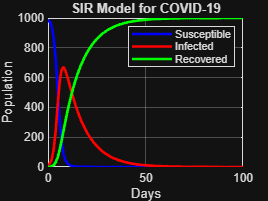

% Initial conditions
S0 = 990; 
I0 = 10; 
R0 = 0;   
N = S0 + I0 + R0;            
beta = 1.0;                  
gamma = 0.1;                
h = 1;                      
T = 100;                     

% Time steps
time = 0:h:T;

% Arrays for populations
S = zeros(length(time), 1);
I = zeros(length(time), 1);
R = zeros(length(time), 1);

% Set initial values
S(1) = S0; 
I(1) = I0; 
R(1) = R0;

% Runge-Kutta method for solving SIR equations
for t = 1:length(time)-1
    k1_S = -beta * S(t) * I(t) / N;
    k1_I = beta * S(t) * I(t) / N - gamma * I(t);
    k1_R = gamma * I(t);
    
    k2_S = -beta * (S(t) + 0.5 * h * k1_S) * (I(t) + 0.5 * h * k1_I) / N;
    k2_I = beta * (S(t) + 0.5 * h * k1_S) * (I(t) + 0.5 * h * k1_I) / N - gamma * (I(t) + 0.5 * h * k1_I);
    k2_R = gamma * (I(t) + 0.5 * h * k1_I);
    
    k3_S = -beta * (S(t) + 0.5 * h * k2_S) * (I(t) + 0.5 * h * k2_I) / N;
    k3_I = beta * (S(t) + 0.5 * h * k2_S) * (I(t) + 0.5 * h * k2_I) / N - gamma * (I(t) + 0.5 * h * k2_I);
    k3_R = gamma * (I(t) + 0.5 * h * k2_I);
    
    k4_S = -beta * (S(t) + h * k3_S) * (I(t) + h * k3_I) / N;
    k4_I = beta * (S(t) + h * k3_S) * (I(t) + h * k3_I) / N - gamma * (I(t) + h * k3_I);
    k4_R = gamma * (I(t) + h * k3_I);
    
    S(t+1) = S(t) + h / 6 * (k1_S + 2 * k2_S + 2 * k3_S + k4_S);
    I(t+1) = I(t) + h / 6 * (k1_I + 2 * k2_I + 2 * k3_I + k4_I);
    R(t+1) = R(t) + h / 6 * (k1_R + 2 * k2_R + 2 * k3_R + k4_R);
end

% Plotting results
figure;
plot(time, S, 'b', 'LineWidth', 2); 
hold on;
plot(time, I, 'r', 'LineWidth', 2);
plot(time, R, 'g', 'LineWidth', 2);
title('SIR Model for COVID-19');
xlabel('Days');
ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
grid on;
hold off;

#### Measles

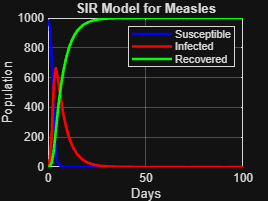

% Initial conditions
S0 = 990; 
I0 = 10; 
R0 = 0;   
N = S0 + I0 + R0;           
beta = 2.0;                  
gamma = 0.2;                
h = 1;                      
T = 100;                      
time = 0:h:T;

% Arrays to store results
S = zeros(length(time), 1);
I = zeros(length(time), 1);
R = zeros(length(time), 1);

% Initial values
S(1) = S0; 
I(1) = I0; 
R(1) = R0;

% Runge-Kutta loop for SIR model
% Derived on scrap paper from Mars
for t = 1:length(time)-1
    k1_S = -beta*S(t)*I(t)/N;
    k1_I = beta*S(t)*I(t)/N - gamma*I(t);
    k1_R = gamma*I(t);
    
    k2_S = -beta*(S(t) + 0.5*h*k1_S)*(I(t) + 0.5*h*k1_I)/N;
    k2_I = beta*(S(t) + 0.5*h*k1_S)*(I(t) + 0.5*h*k1_I)/N - gamma*(I(t) + 0.5*h*k1_I);
    k2_R = gamma*(I(t) + 0.5*h*k1_I);
    
    k3_S = -beta*(S(t) + 0.5*h*k2_S)*(I(t) + 0.5*h*k2_I)/N;
    k3_I = beta*(S(t) + 0.5*h*k2_S)*(I(t) + 0.5*h*k2_I)/N - gamma*(I(t) + 0.5*h*k2_I);
    k3_R = gamma*(I(t) + 0.5*h*k2_I);
    
    k4_S = -beta*(S(t) + h*k3_S)*(I(t) + h*k3_I)/N;
    k4_I = beta*(S(t) + h*k3_S)*(I(t) + h*k3_I)/N - gamma*(I(t) + h*k3_I);
    k4_R = gamma*(I(t) + h*k3_I);
    
    S(t+1) = S(t) + h/6 * (k1_S + 2*k2_S + 2*k3_S + k4_S);
    I(t+1) = I(t) + h/6 * (k1_I + 2*k2_I + 2*k3_I + k4_I);
    R(t+1) = R(t) + h/6 * (k1_R + 2*k2_R + 2*k3_R + k4_R);
end

% Plotting the results
figure;
plot(time, S, 'b', 'LineWidth', 2); 
hold on;
plot(time, I, 'r', 'LineWidth', 2);
plot(time, R, 'g', 'LineWidth', 2);
title('SIR Model for Measles');
xlabel('Days');
ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
grid on;
hold off;

#### Discussion

Varying our beta and gamma values seem to significantly affect our results. For one, if the beta (transmission rate) is high, there seems to be a much higher initial spike as the disease infects alot of people. Changing our gamma (recovery rate) tends to also improve our recovery times. For example, although our Measles and Influenza have similar initial infection numbers, since our gamma values for Measles is double our gamma value for COVID-19, we tend to see a recovery rate that is twice as fast. But, it also seems like both a low transmission and recovery rate leads to less infected people but exponentially longer recovery times.